% Clear command window, workspace, and close all figures
clc
clear all
close all

% Read stock data from CSV file
financialData = readtable("yahoo_stock.csv");


% Remove the last column
financialData(:,end) = [];

% Look for missing values
missingVals = sum(ismissing(financialData));

% Find the range of dates in the dataset
dateRange = [min(financialData.Date) max(financialData.Date)];

% Make "Close" the last variable since it is the response
closingPrices = financialData.Close;
financialData(:,"Close") = [];
financialData.Close = closingPrices;

% Display a summary of the dataset
summary(financialData)

Variables:

    Date: 1825×1 datetime

        Properties:
            Description:  Date
        Values:

            Min       2015-11-23
            Median    2018-05-23
            Max       2020-11-20

    High: 1825×1 double

        Properties:
            Description:  High
        Values:

            Min          1847 
            Median     2696.2 
            Max          3646 

    Low: 1825×1 double

        Properties:
            Description:  Low
        Values:

            Min        1810.1 
            Median     2667.8 
            Max        3600.2 

    Open: 1825×1 double

        Properties:
            Description:  Open
        Values:

            Min        1833.4 
            Median     2685.5 
            Max        3612.1 

    Volume: 1825×1 double

        Properties:
            Description:  Volume
        Values:

            Min       1.2965e+09
            Median 

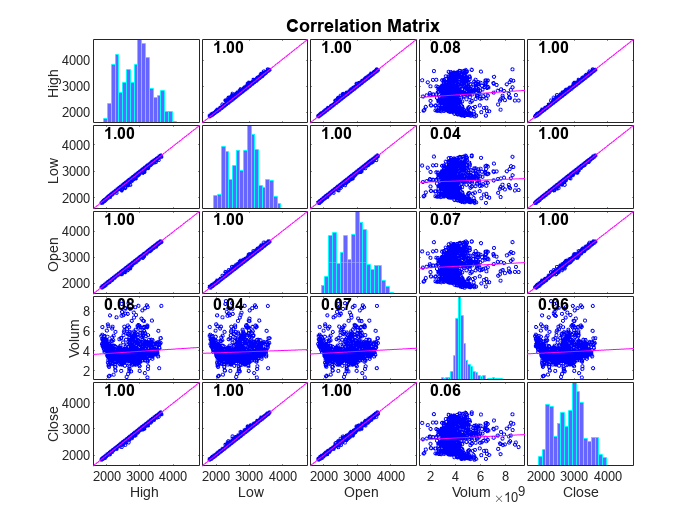


% Plot correlation matrix
corrplot(financialData(:,2:end), 'type', 'Pearson');
title('Correlation Matrix');

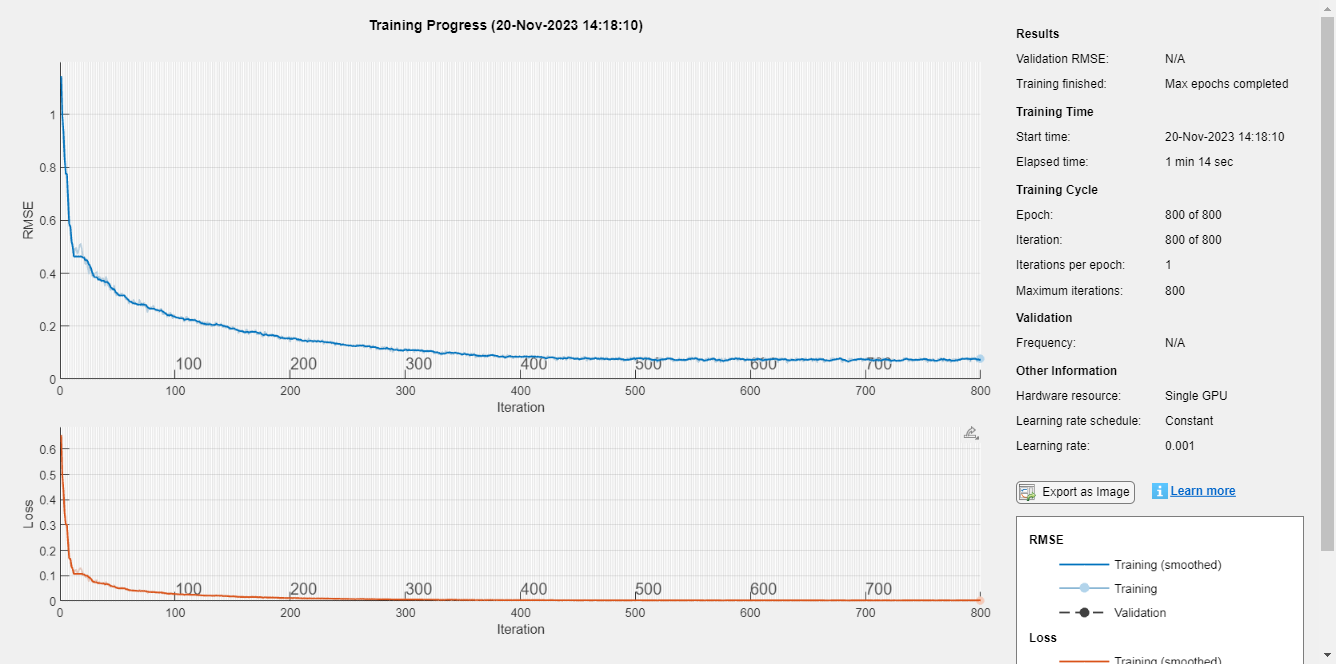


% Partition X and Y variables
% Convert the data table to matrix
featuresX = table2array(financialData(1:end-1,["High","Low","Open"]));
responseY = financialData(2:end,6); % For one-ahead prediction
responseY = table2array(responseY(:,"Close"));

% Normalize the featuresX and responseY
featuresX = zscore(featuresX,1);
responseY = zscore(responseY,1);

% Test-Train partition
nObservations = numel(responseY);

% Train model
sequenceLength = 9;

clearvars featuresXTest featuresXTrain responseYTest responseYTrain

numSequences = floor(numel(responseY)/sequenceLength);
counter = 1;

for i = 1:numSequences-2
    indices = counter:counter+sequenceLength;
    featuresXTrain{1,i} = featuresX(indices,:)';
    responseYTrain{1,i} = responseY(indices)';
    counter = counter + sequenceLength;
end

i = 1;
for j = numSequences
    indices = counter:counter+sequenceLength;
    featuresXTest{1,i} = featuresX(indices,:)';
    responseYTest{1,i} = responseY(indices)';
    counter = counter + sequenceLength;
    i = i+1;
end

numChannels = 3;

% Define LSTM layers
layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(100)
    fullyConnectedLayer(1)
    regressionLayer];

% Set training options
options = trainingOptions("adam", ...
    'MaxEpochs', 800, ...
    'SequencePaddingDirection', "left", ...
    'Shuffle', "every-epoch", ...
    'Plots', "training-progress", ...
    'Verbose', 0, ...
    'InitialLearnRate', 0.001);

% Train LSTM network
net = trainNetwork(featuresXTrain, responseYTrain, layers, options);

responseYTestHat    = predict(net, featuresXTest);
responseYTrainHat   = predict(net, featuresXTrain);

% Plotting
figure; 
nexttile;
plot(responseYTest{1,1});
hold on 
plot(responseYTestHat{1,1});
title("Test partition three-ahead predictions");
axis tight

nexttile;
plot(responseYTrain{1,1});
hold on 
plot(responseYTrainHat{1,1});
title("Training partition three-ahead predictions");
axis tight


% RNN

clearvars XTest XTrain YTest YTrain

% Partition data for RNN training
XTrain = featuresX(1:end/2-2,:);
YTrain = responseY(2:end/2+1-2);

% Create and train RNN
net = layrecnet(1:2,10);
trainedNet = train(net,XTrain', YTrain');

% RNN testing
XTest       = featuresX(round(end/2)+1:end-2,:);
YTest       = responseY((round(end/2)+2):end-1);
YTestPred   = trainedNet(XTest');
YCalPred    = trainedNet(XTrain');

% Plotting for RNN
figure;
plot(YCalPred);
title("Calibration Partition");
hold on 
plot(YTrain);
axis tight


figure;
plot(YTestPred);
title("Test Partition");
hold on 
plot(YTest);
axis tight